The linear oscillator $y''+y=0$ has perfect sinusoidal motion with period 1. The true pendulum, $y''+\sin(y)=0$, has a smaller restoring force, hence a longer period. The discrepancy grows with the amplitude. 

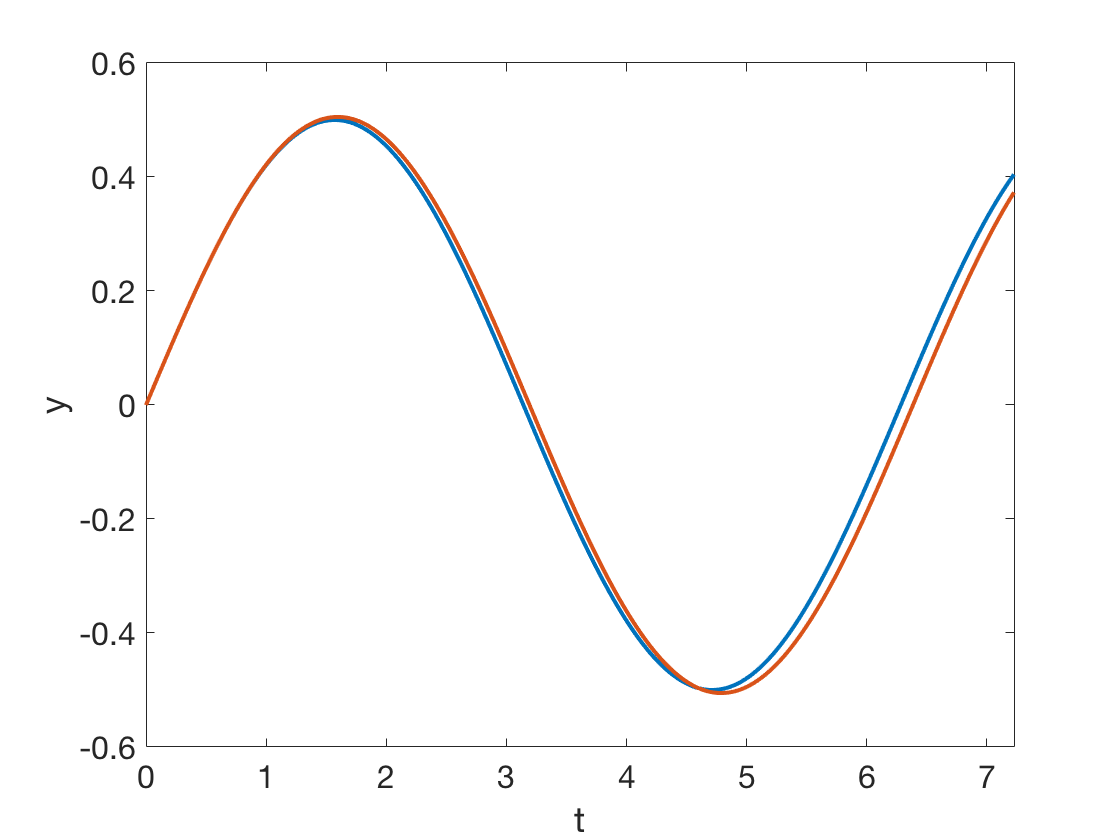

linosc = chebop(@(y) diff(y,2) + y,d,[0 0],[]);
pend = chebop(@(y) diff(y,2) + sin(y),d,[0 0],[]);
clf
linosc.lbc = [ 0 0.5 ];
pend.lbc = [ 0 0.5 ];
plot([linosc\0,pend\0])
xlabel t, ylabel y

title('Linear vs true pendulum')

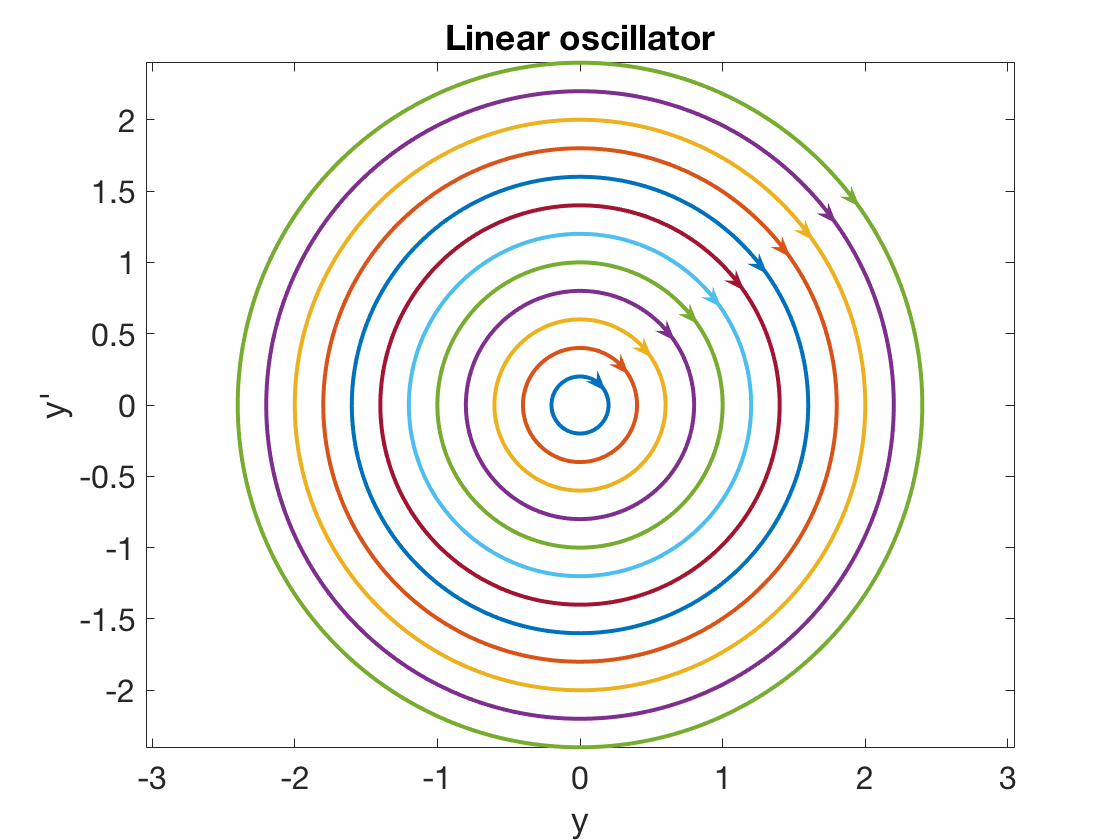

addpath ~/Dropbox/working/chebfun
d = [0 2.3*pi];
linosc = chebop(@(y) diff(y,2) + y,d,[0 0],[]);
clf
for v0 = 0.2:.2:2.4
    linosc.lbc = [ 0 v0 ];
    y = linosc\0;
    arrowplot(y,diff(y))
    hold on
end
axis equal
xlabel('y'), ylabel('y''')
title('Linear oscillator')

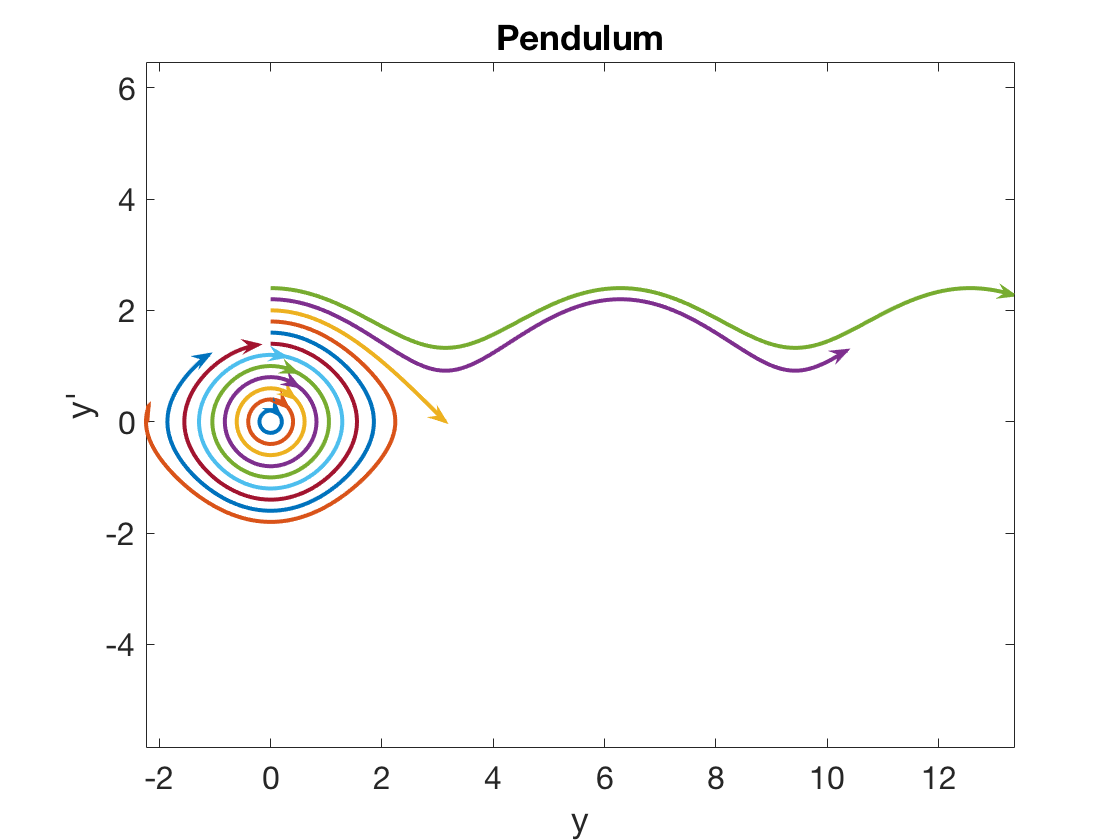

for v0 = 0.2:.2:2.4
    pend.lbc = [ 0 v0 ];
    y = pend\0;
    arrowplot(y,diff(y))
    hold on
end
axis equal
xlabel('y'), ylabel('y''')
title('Pendulum')